# **Lab 11. Adaptive feedback linearization**

During this lab we will implement an adaptive feedback linearization control scheme using radial basis function neural networks in order to learn the non-linear functions of the system during the control task, and not before (as the NARMA-L2 controller does).

## 1. Problem formulation

Let us consider again the following single-input single-output non-linear system, expressed by the state equation:


$$\dot{y} =f\left(y\right)+g\left(y\right)u$$


where the non-linear functions $f\left(\cdot \right)$ and $g\left(\cdot \right)$ have the following structure:


$$f\left(y\right)=-1-0\ldotp 01y^2 ,$$
               
$$g\left(y\right)=40\;\frac{y+1}{y+40}$$


This time, we want to implement an adaptive feedback linearization control scheme assuming we need to lear the non-linear functions of the system during the control task using radial basis function neural networks as real-time approximators.

### 1.1. System implementation

The first thing we need to do is to define a subsystem in Simulink in which we will implement the behaviour of the non-linear system. This subsystem will be considered as a blackbox from us, since we will assume we do not have any information regarding the real behaviour of the non-linear system, but at the same time we need to simulate it.

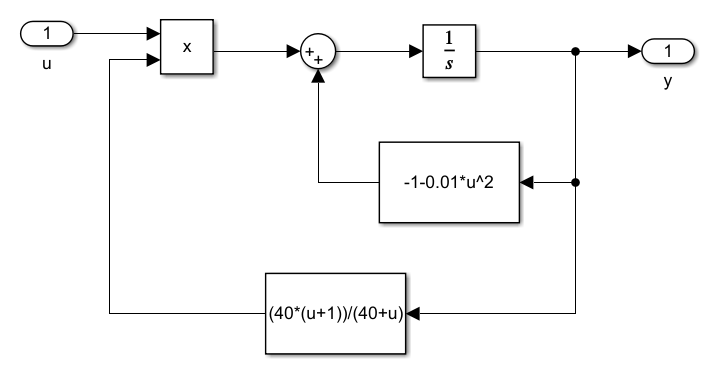

### 1.2. Remembering the adaptation law

In adaptive feedback linearization we are interested in canceling the non-linear dynamics of the system and substitute it with the dynamics of a first order linear system, in order to let the system follow a reference trajectory. We design the control law as:


$$u=\frac{1}{\hat{g} \left(y\right)}\left\lbrack -\hat{f} \left(y\right)-\lambda e+y_{\textrm{ref}} \right\rbrack$$


Since the approximations of the non-linear functions are expressed as linear-in-the-parameters functions:


$$\hat{f} \left(x\right)=\varphi_f^T \left(x\right){\hat{\theta} }_f ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\hat{g} \left(x\right)=\varphi_g^T \left(x\right){\hat{\theta} }_g$$


we also need an adaptation law for the two vectors of parameters:


$${\hat{\theta} }_f =\gamma_f \;\varphi_f \left(x\right)\;e,\;\;\;\;\;\;\;\;\;\;\;\;\;\;{\hat{\theta} }_g =\gamma_g \;\varphi_g \left(x\right)\;e\;u$$


To avoid that the approximation of the functions grow to infinity, and so to avoid the saturation of the control action, we bound them.

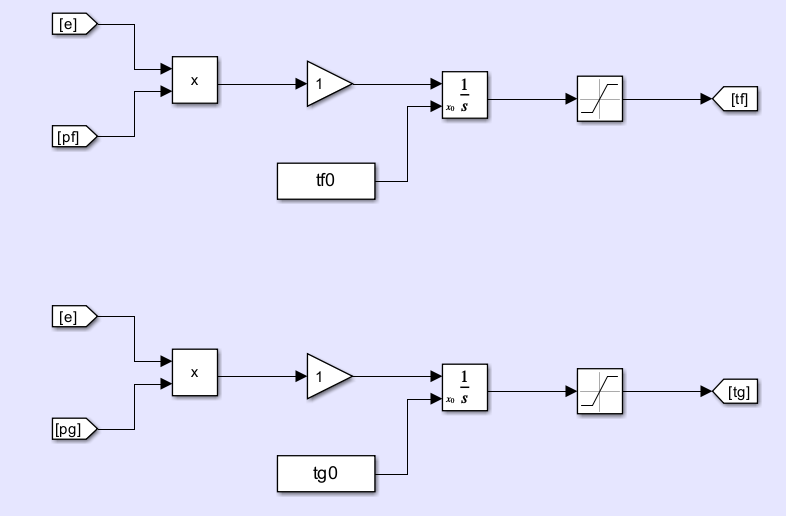

## 2. Implementing the RBF neural networks

In order to estimate the non-linear functions of the system, we use two radial basis function neural networks, which receive the output of the system as an input and compute at each iteration the best estimate of the two functions, which are the outputs.

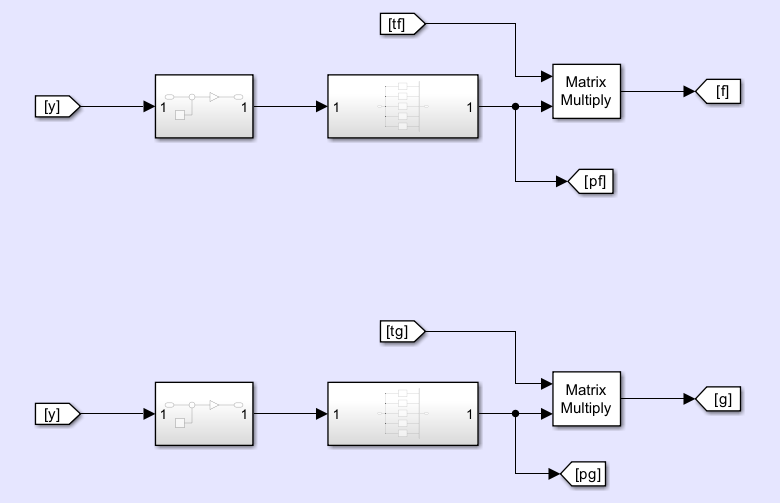

### 2.1. Preliminary operations

The output values of the system is first normalized by emoving the offset and dividing for a constant so that after normalization all the values of the output of the system are bounded in a unitary interval, so between $\left\lbrack -1,1\right\rbrack$.

% Normalization coefficients
C =   40;
G = 1/20;

###  2.2. Initialization of the neural networks

We need to define the placement of the radial basis functions of each of the two neural networks. We first decide to use five neurons, so five gaussians functions (which are radial basis functions) and we decide to place them uniformely with the same dispersion.

% Centers
c1 = -1.0;
c2 = -0.5;
c3 =  0.0;
c4 =  0.5;
c5 =  1.0;

% Dispersions
s1 = 1;
s2 = 1;
s3 = 1;
s4 = 1;
s5 = 1;

Each neuron will cover a certain part of the input space, usually each point will be covered by two gaussians. Finally we initialize the learning rates and the vectors of the parameters. We recall that we do not want our approximation $\hat{g} \left(x\right)$ to go to zero, because otherwise the control action will tend to infinity, so we do not initialize the vector of its parameters to zero but to one.

% Learning rates
gf = 50;
gg = 10;

% Parameters
tf0 = zeros(5,1);
tg0 =  ones(5,1);

## 3. Visualizing results

Let's run a simulation of 100 seconds in order to evaluate the behaviour of the system.

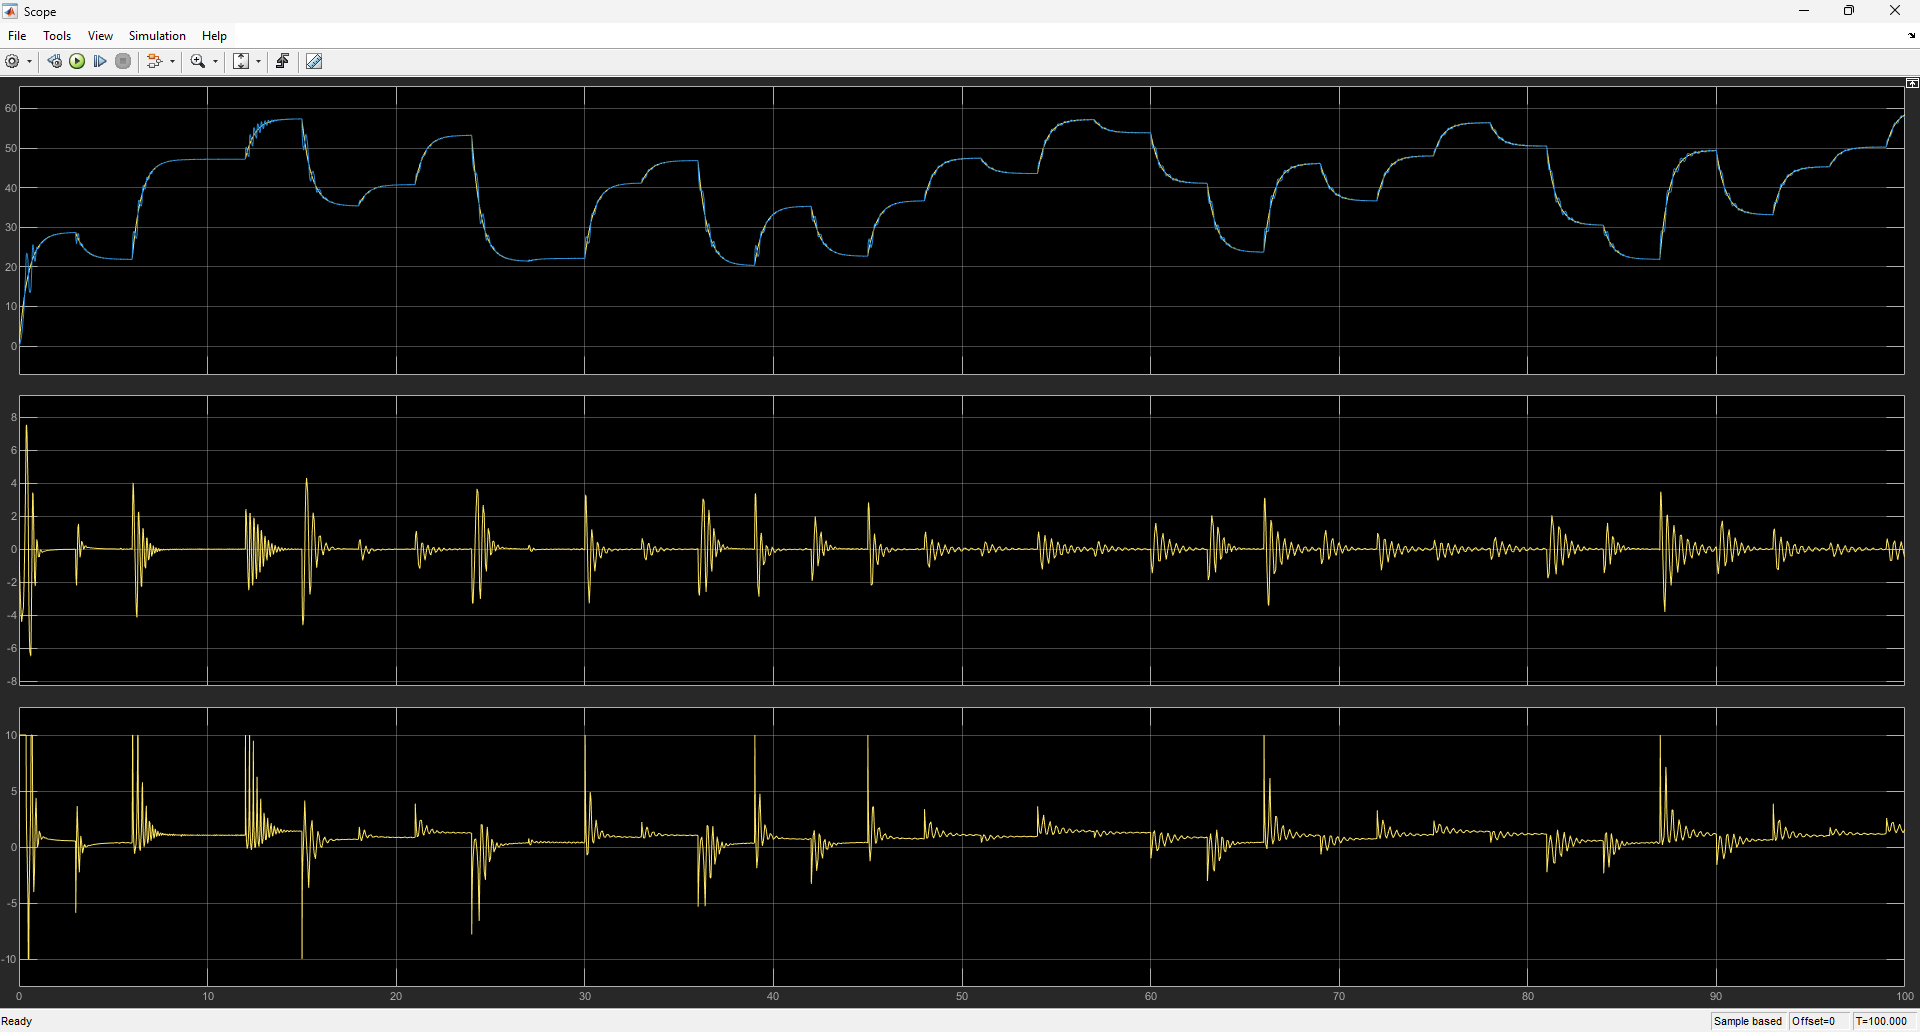

As we can see there are some oscillations but then the output slowly reaches the reference. Also the error at steady state is zero. In transient time the performance are not very satisfying because we make some errors each time the reference changes. We can also see that the peaks of the error slowly tend to be smaller over time, meaning that our adaptation policy is working.

We can try to improve the adaptation law (since some of the parameters oscillate over time) by increasing the learning rates.